Section 1. Ring performance analysis

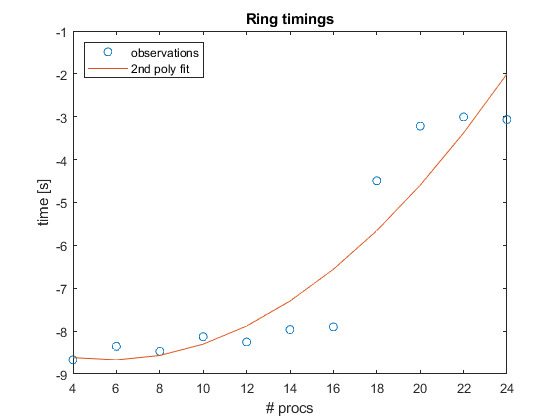

% Manually copied time outputs for x processors
y = [0.00017176,0.00023508, 0.00020885, 0.00029443, 0.00026041, 0.00034799, 0.00036976, 0.01118734, 0.04004431, 0.04958053, 0.04665447];
x = [4, 6, 8, 10, 12, 14, 16, 18, 20, 22, 24];

y = log(y);

plot(x,y,'o');
[p,~,mu] = polyfit(x,y, 2);
f = polyval(p,x,[],mu);
hold on
plot(x,f)
xlabel('# procs')
ylabel('time [s]')
legend('observations','2nd poly fit', "Location","northwest") 
title('Ring timings')
hold off

Section 2. PingPong Benchmarking

Now reading D:\units\HPC\Assignment\2\intel_cpu_mbnode.csv


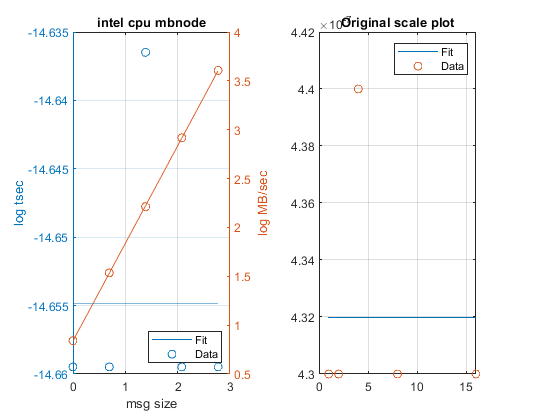

Now reading D:\units\HPC\Assignment\2\intel_gpu_mbnode.csv


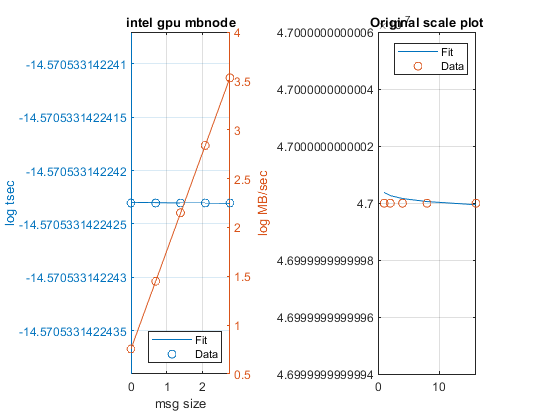

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_mbcore.csv


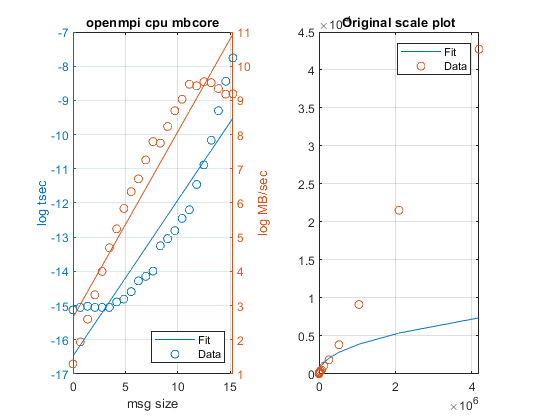

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_mbnode.csv


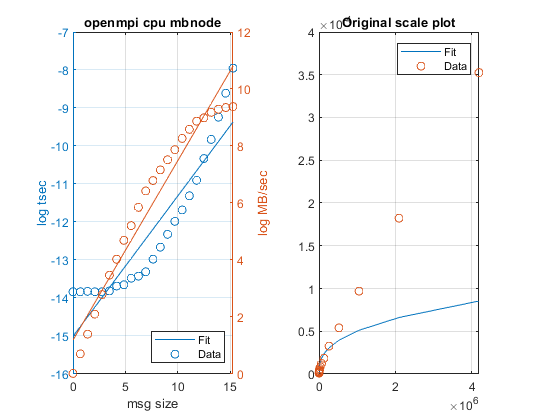

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_mbnode_tcp.csv


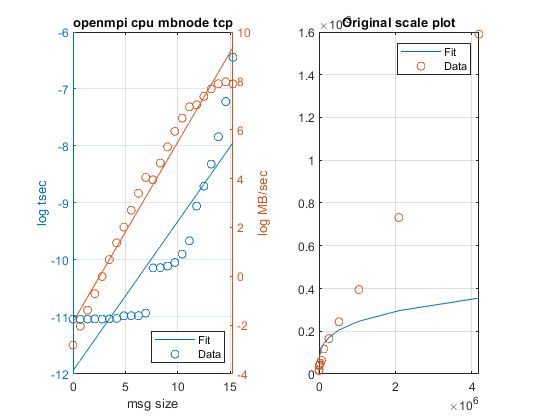

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_mbsocket.csv


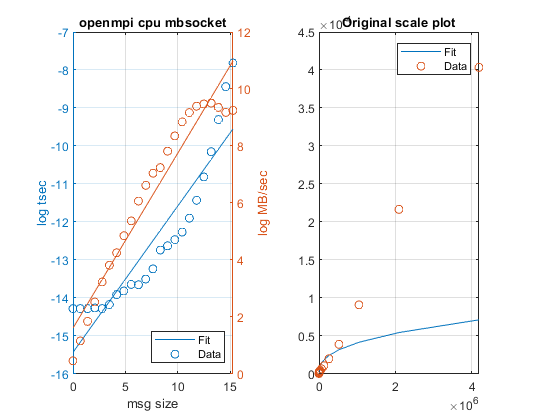

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_tcp.csv


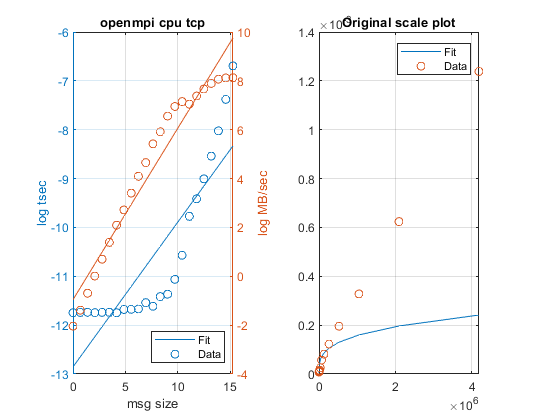

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_tcpvader.csv


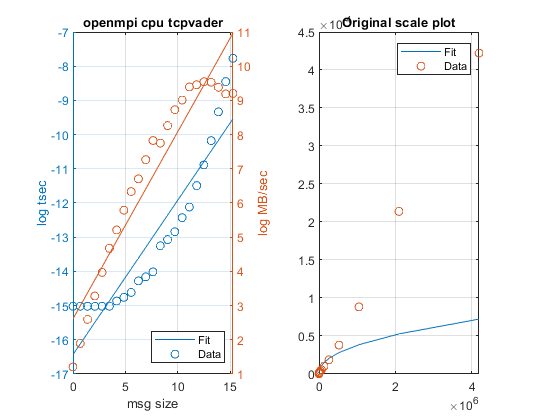

Now reading D:\units\HPC\Assignment\2\openmpi_cpu_vader.csv


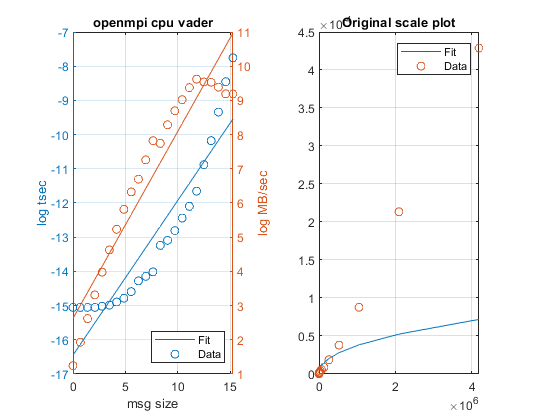

Now reading D:\units\HPC\Assignment\2\openmpi_gpu_mbnode.csv


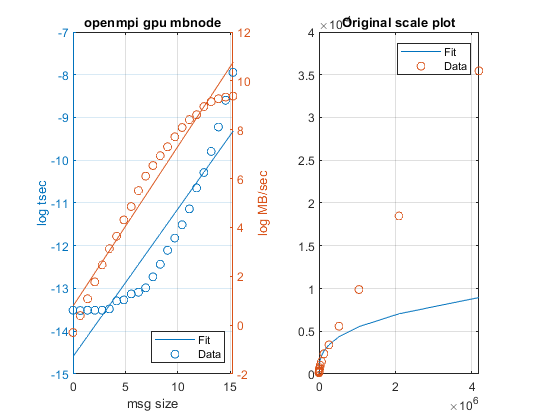

Now reading D:\units\HPC\Assignment\2\openmpi_gpu_mbnode_tcp.csv


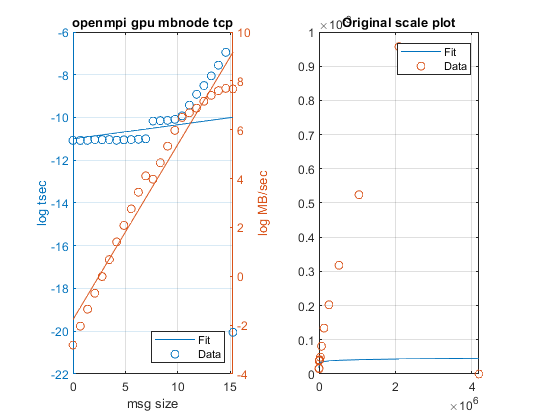

format short g
clear all 

% Gets all raw csv-s from command outputs
myFiles = dir(fullfile(pwd,'*.csv'));
fit_all = [];
for k = 1:length(myFiles)
baseFileName = myFiles(k).name;
fullFileName = fullfile(pwd, baseFileName);
fprintf(1, 'Now reading %s\n', fullFileName);

tbl = importfile(fullFileName); 

% Fix mistake in multiplying by 1e6 all tusec columns, instead of 1e-6
tbl.tusec = tbl.tusec*1e-6;
tsec = tbl.tusec*1e-6;

x = [];
y = [];

% Original data
x = tbl.size(2:end)';
y1 = tsec(2:end);
y2 = tbl.Mbytessec(2:end);
y = [y1 y2];

%Logarithms of data
log_x = log(x);
log_y1 = log(y1); 
log_y2 = log(y2);
y_log = [log_y1 log_y2];

% Linear fit of data in logarithmic scale
fit1 = polyfit(log_x,log_y1,1);
fit2 = polyfit(log_x,log_y2,1);

% Generate linear fit curve in logarithmic scale
if contains(fullFileName, "openmpi")
xVec = linspace(log_x(1),log_x(end),23);
else
xVec = linspace(log_x(1),log_x(end),5);
end
h1_fit = polyval(fit1,xVec);
h2_fit = polyval(fit2,xVec);

FileName = erase(fullFileName, ".csv");
level = wildcardPattern + "\";
pat = asManyOfPattern(level);
title_plot = strrep(extractAfter(FileName,pat), '_' , ' ');

% Plot logarithmic data and fit
figure
subplot(1,2,1);
yyaxis left
plot(xVec,h1_fit,xVec,log_y1,'o');
ylabel('log tsec')
hold on
yyaxis right
plot(xVec,h2_fit,xVec,log_y2,'o');
ylabel('log MB/sec')
grid on;
legend('Fit','Data', "Location","southeast")
xlabel ('msg size')
title(title_plot)
hold off
% Plot linear scale
subplot(1,2,2)
plot(x,x.^fit1(1)*exp(fit1(2)),x,y1,'o');
grid on;
legend('Fit','Data');
title('Original scale plot')

% Convert from logarithmic scale to linear scale for predictions

max_bandwidth = max(tbl.Mbytessec);
latency = tbl.tusec(1);

% Save in cell to get all coeffs and intercepts in one place
coeff_latency{k, 1} = extractAfter(FileName,pat);
coeff_latency{k,2} = fit1(1);
b1{k, 1} = extractAfter(FileName,pat);
b1{k, 2} = fit1(2);
tcomp_fit = x.^coeff_latency{k,2}*exp(b1{k,2});

coeff_bw{k, 1} = extractAfter(FileName,pat);
coeff_bw{k, 2} = fit2(1);
b2{k, 1} = extractAfter(FileName,pat);
b2{k, 2} = fit2(2);
tbw_fit = x.^coeff_bw{k,2}*exp(b2{k,2});

tbl.tusec_computed(1) = latency;
tbl.mbsec_computed(1) = 0;

tbl.tcomm_model(1) = latency;

j = 1;
for i = 2: size(tbl, 1)
    tbl.tusec_computed(i) = tcomp_fit(j)*1e6; 
    rmse_tbl{j, 1} = sqrt(mean((tbl.tusec(i) - tbl.tusec_computed(i)).^2));  % Root Mean Squared Error
    tbl.mbsec_computed(i) = round(tbw_fit(j), 4);
    tbl.tcomm_model(i) = latency + (tbl.size(i)/max_bandwidth); 
    rmse_tbl{j, 2} = sqrt(mean((tbl.tusec(i) - tbl.tcomm_model(i)).^2));
    j = j + 1;
end

rmse_all{k, 1} = extractAfter(FileName,pat);
rmse_all{k, 2} = mean(cell2mat(rmse_tbl(:,1)));
rmse_all{k, 3} = mean(cell2mat(rmse_tbl(:,2)));

% Add a number in the end of the csv file to not overwrite raw files
name = strcat(FileName, int2str(k), '.csv');
%writetable(tbl, name);
end